# Oskar Chrostowski 

# Lista 2

**Zad. 1.**  Utwórz wektor `t` o 10 elementach 1,2,3...10. 

t=[1:10]

t =      1     2     3     4     5     6     7     8     9    10


Oblicz:


$$x = t\sin(t)$$


x= t.*sin(t)

x =     0.8415    1.8186    0.4234   -3.0272   -4.7946   -1.6765    4.5989    7.9149    3.7091   -5.4402



$$y = \frac{t-1}{t+1}$$


y=(t-1)/(t+1)

y = 0.7426


$$z = \frac{\sin(t^2)}{t^2}$$


z=sin(t.^2)./t.^2

z =     0.8415   -0.1892    0.0458   -0.0180   -0.0053   -0.0275   -0.0195    0.0144   -0.0078   -0.0051


**Zad.2.** Równanie prostej ma postać $y=m\;x+c$, gdzie wartosći $m$ i $c$ są stałe. Oblicz współrzędne $y$przy nachyleniu $m=0\ldotp 5$ oraz $c=-2$ dla następujących współrzędnych $x$:

`x = 0, 1.5, 3, 4, 5, 7, 9, 10.`

m=0.5

m = 0.5000

c=-2

c = -2

x = [0, 1.5, 3, 4, 5, 7, 9, 10]

x =          0    1.5000    3.0000    4.0000    5.0000    7.0000    9.0000   10.0000


y = m.*x+c

y =    -2.0000   -1.2500   -0.5000         0    0.5000    1.5000    2.5000    3.0000


Proszę narysować otrzymane wyniki poleceniem: `plot(x,y)`

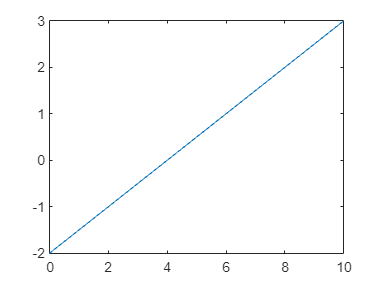

plot(x,y)

**Zad.3** Utwórz tablicę $A\left(10,10\right)$ zawierającą losowe liczby całkowite z przedziału $\left(0,50\right)$. 

A=round(rand(10,10)*50)

A =     44    35    17    38    29    13    38    42    38    20
    27    49    21    37    43    16    12    41    49     0
    18    14     8    42     2    20    37    28    12    27
    10     7    41     8    44    20    35    13    26    10
    22    34    31    23    20    19    41    34     3    11
    48    45    37    31     2    30    41    12    38    16
     6    31    40    47    37     8    15    23    30     5
    24    45     3    42     8     9    15    19    43    37
    43    10    48    45     7     5    26    27    49    37
     2    38    25    29    30    16    16    50    46    27


Napisz jedną instrukcję, która przekształca tablicę $A$ w następujący sposób:

- usuwa trzeci wiersz

a3=A;  
a3(3,:)=[]

a3 =     44    35    17    38    29    13    38    42    38    20
    27    49    21    37    43    16    12    41    49     0
    10     7    41     8    44    20    35    13    26    10
    22    34    31    23    20    19    41    34     3    11
    48    45    37    31     2    30    41    12    38    16
     6    31    40    47    37     8    15    23    30     5
    24    45     3    42     8     9    15    19    43    37
    43    10    48    45     7     5    26    27    49    37
     2    38    25    29    30    16    16    50    46    27


- usuwa wiersze o parzstych numerach

b3=A;
b3(2:2:10,:)=[]

b3 =     44    35    17    38    29    13    38    42    38    20
    18    14     8    42     2    20    37    28    12    27
    22    34    31    23    20    19    41    34     3    11
     6    31    40    47    37     8    15    23    30     5
    43    10    48    45     7     5    26    27    49    37


- zastępuje trzeci wiersz wierszem postaci: 1, 2, 3, ...

c3=A;
c3(3,:)=[1:10]

c3 =     44    35    17    38    29    13    38    42    38    20
    27    49    21    37    43    16    12    41    49     0
     1     2     3     4     5     6     7     8     9    10
    10     7    41     8    44    20    35    13    26    10
    22    34    31    23    20    19    41    34     3    11
    48    45    37    31     2    30    41    12    38    16
     6    31    40    47    37     8    15    23    30     5
    24    45     3    42     8     9    15    19    43    37
    43    10    48    45     7     5    26    27    49    37
     2    38    25    29    30    16    16    50    46    27


- dopisuje na dole tablicy wiersz samych jedynek

d3=A;
d3(end+1,:)= ones()

d3 =     44    35    17    38    29    13    38    42    38    20
    27    49    21    37    43    16    12    41    49     0
    18    14     8    42     2    20    37    28    12    27
    10     7    41     8    44    20    35    13    26    10
    22    34    31    23    20    19    41    34     3    11
    48    45    37    31     2    30    41    12    38    16
     6    31    40    47    37     8    15    23    30     5
    24    45     3    42     8     9    15    19    43    37
    43    10    48    45     7     5    26    27    49    37
     2    38    25    29    30    16    16    50    46    27


- zamienia miejscami wiersz 1 i 4

e3=A;
w1=e3(1,:);
w4=e3(4,:);
e3(1,:)=w4;
e3(4,:)=w1;
e3

e3 =     10     7    41     8    44    20    35    13    26    10
    27    49    21    37    43    16    12    41    49     0
    18    14     8    42     2    20    37    28    12    27
    44    35    17    38    29    13    38    42    38    20
    22    34    31    23    20    19    41    34     3    11
    48    45    37    31     2    30    41    12    38    16
     6    31    40    47    37     8    15    23    30     5
    24    45     3    42     8     9    15    19    43    37
    43    10    48    45     7     5    26    27    49    37
     2    38    25    29    30    16    16    50    46    27


- zamienia miejscami kolumny drugą i ostatnią

f3=A;
wp=f3(2,:);
we=f3(end,:);
f3(2,:)=we;
f3(end,:)= wp;
f3

f3 =     44    35    17    38    29    13    38    42    38    20
     2    38    25    29    30    16    16    50    46    27
    18    14     8    42     2    20    37    28    12    27
    10     7    41     8    44    20    35    13    26    10
    22    34    31    23    20    19    41    34     3    11
    48    45    37    31     2    30    41    12    38    16
     6    31    40    47    37     8    15    23    30     5
    24    45     3    42     8     9    15    19    43    37
    43    10    48    45     7     5    26    27    49    37
    27    49    21    37    43    16    12    41    49     0


**Zad. 4**. Utwórz tablicę $3\times 4$ z losowymi wartościami. Przekształć ją funkcją `reshape()` na wszystkie możliwe sposoby.

a4=round(rand(3,4)*10)

a4 =      7     8     2    10
     9     5     5     4
     1     7     7     1


reshape(a4,1,12)

ans =      7     9     1     8     5     7     2     5     7    10     4     1


reshape(a4,4,3)

ans =      7     5     7
     9     7    10
     1     2     4
     8     5     1


reshape(a4,12,1)

ans =      7
     9
     1
     8
     5
     7
     2
     5
     7
    10


reshape(a4,2,6)

ans =      7     1     5     2     7     4
     9     8     7     5    10     1


reshape(a4,6,2)

ans =      7     2
     9     5
     1     7
     8    10
     5     4
     7     1


**Zad. 5.** Utwórz tablicę $3\times 5$ z losowymi wartościami z zakresu -5 do 5 i przechowaj ją w jakiejś zmiennej. Utwórz inną zmienną, w której będą warstości bezwględne elementów pierwszej tablicy.

a5=round(rand(3,5)*10-5)

a5 =     -4     2     0    -3     3
     1    -2     5     3    -2
     3     4    -4     4    -3


b5=abs(a5)

b5 =      4     2     0     3     3
     1     2     5     3     2
     3     4     4     4     3
